# cAMPFreSimulation_Interactive

不同周期不同占空比光信号刺激bPAC生产cAMP，调控下游基因表达

Shuai Yang 2023/2/14

考虑bPAC按恒定速率$\beta$失活，在周期T，占空比P的光照下，cAMP浓度的变化$x(t)$，

周期内蛋白平均表达$\bar y$

#### % 参数定义与选择

% k= k0[bPAC*], uM/s；光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率

k =0.0056; % uM/s;cAMP生产
gamma = 0.0033;% s-1,cAMP被降解率 gamma
beta = 0.06; % s-1, bPAC失活率
P = 0.46; % 占空比(0,1]

% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;

% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数 n2

n1 = 2; % 暂时不用
K1 =2; % 2 uM
n2 = 1; % 暂时不用
K2 = 0.01; % 0.01uM = 10 nM

% 基因元件数目

Vfr = 0.27;% 0.27uM TF因子数目
DNA = 0.05; % 0.05uM 启动子的DNA数目
lambda = Vfr/K2;

% 蛋白表达

gamma2 = 0.00027;  %蛋白的降解率 2.7e-4 s-1
k2 = 0.16 ;% s-1 蛋白生产率 = 转录率*翻译率/mRNA降解率 = 0.02*0.04/0.005
ymax = k2/gamma2*DNA;% 蛋白的最大表达量 uM

#### % 数值积分模拟蛋白输出

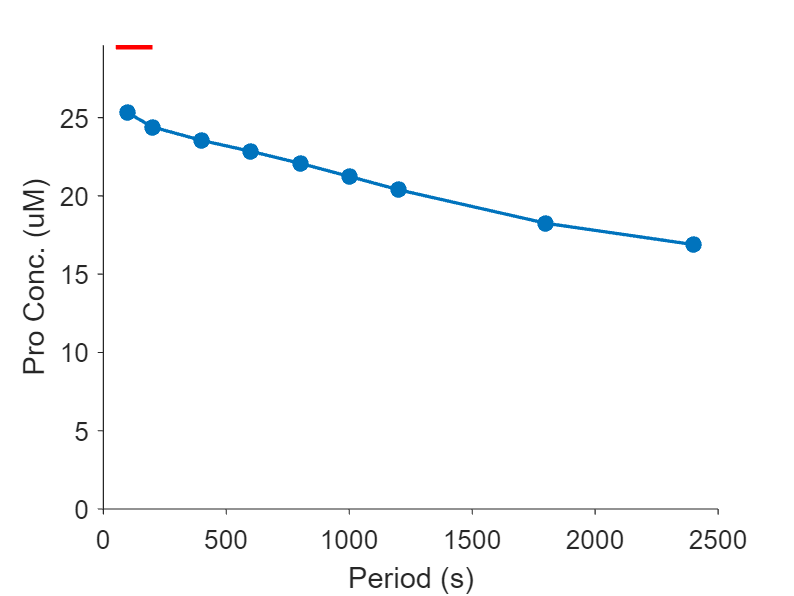

xlog = false;
% Tset = [100:50:300,400:100:1000,1200:400:2400];
Tset = [100,200,400,600,800,1000,1200,1800,2400];
f1 = meanProPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,ymax);


if xlog
    ax1 = gca;
    set(ax1,'XScale','log')
end

#### % cAMP 和激活DNA输出

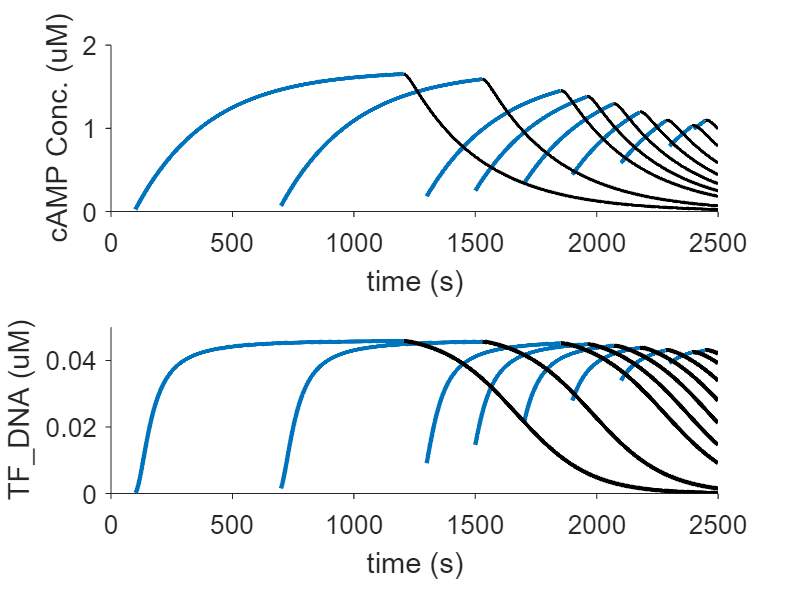

% Tset = [50,100,200,400,600,800,1000,1200,1600,1800,2400];
f2 = cAMPactDNAPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,DNA);

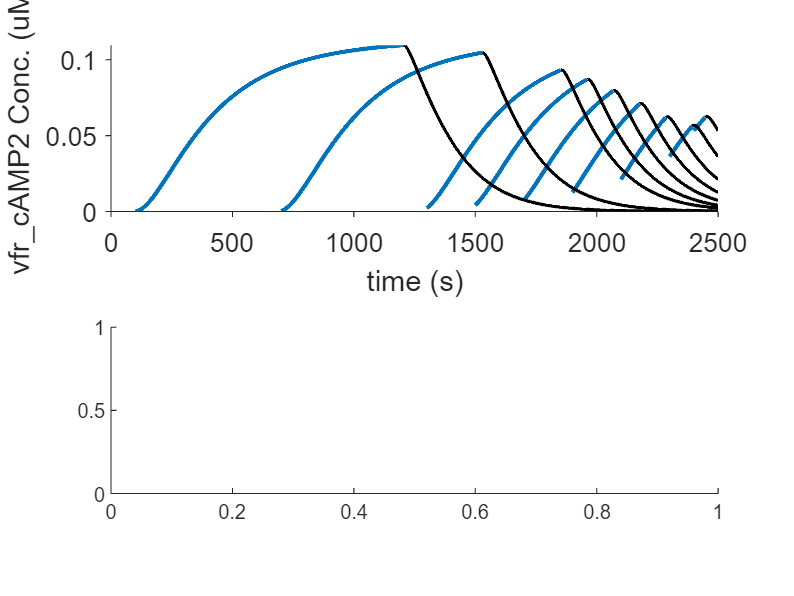

f3 = boundProPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,DNA);

cAMP浓度的变化$x(t)$：


$$x(t) =
\begin{cases}
\frac{{\gamma x_{Low}-k}}{\gamma}e^{-\gamma t}+\frac{k}{\gamma},  &&  0\le t\le TP & \\[2ex]
(x_{Middle}-\frac{k}{\gamma-\beta})e^{-\gamma (t-TP)}+\frac{k}{\gamma-\beta}e^{-\beta (t-TP)},  &&  TP< t\le T & \\[2ex]
\end{cases}$$



$$x_{Middle} = \frac{\frac{k}{\beta-\gamma}(e^{-\gamma T}-e^{-\beta T+\beta TP -\gamma TP})+\frac{k}{\gamma}(1-e^{-\gamma TP})}{1-e^{-\gamma T}}$$



$$x_{Low} = x_{Middle}e^{-\gamma (T-TP)}+\frac{k}{\beta-\gamma}(e^{-\gamma (T-TP)}-e^{-\beta (T-TP)})$$


如果$\beta = \gamma$


$$x(t) =
\begin{cases}
\frac{{\gamma x_{Low}-k}}{\gamma}e^{-\gamma t}+\frac{k}{\gamma},  &&  0\le t\le TP & \\[2ex]
x_{Middle}e^{-\gamma (t-TP)}+k(t-TP)e^{-\gamma (t-TP)},  &&  TP< t\le T & \\[2ex]
\end{cases}$$



$$x_{Middle} = \frac{k(T-TP)e^{-\gamma T}+\frac{k}{\gamma}(1-e^{-\gamma TP})}{1-e^{-\gamma T}}$$



$$x_{Low} = (x_{Middle}+k(T-TP))e^{-\gamma (T-TP)}$$


function x = cAMPOutPut(t,T,k,gamma,beta,P)

if gamma ~= beta    
x_Mid = (k/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
    +k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
x_Low = x_Mid*exp(-gamma*(T-T*P))...
    +k/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
    ((x_Mid+k/(beta-gamma))*exp(-gamma*(t-T*P)) ...
    -k/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);
end

if gamma == beta
    x_Mid = (k*(T-T*P)*exp(-gamma*T)+k/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
    x_Low =  (x_Mid+k*(T-T*P))*exp(-gamma*(T-T*P));
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_Mid+k*(t-T*P)).*exp(-gamma*(t-T*P)).*(t>T*P);
end

end

function u = actDNAOutPut(t,T,k,gamma,beta,P,K1,K2,Vfr)
% t 时间 T 周期

lambda = Vfr/K2;

x = cAMPOutPut(t,T,k,gamma,beta,P);

xx = x/K1;
u = lambda./((1+lambda)+1./xx.^2);
end

function bp = boundProOutPut(t,T,k,gamma,beta,P,K1,K2,Vfr)
% t 时间 T 周期


x = cAMPOutPut(t,T,k,gamma,beta,P);

bp = Vfr* 1./((K1./x).^2 + 1);
end

function f1 = cAMPactDNAPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,DNA)

dt = 1; %时间间隔 
f1 = figure;
% ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t = 0:dt:T;

    x = cAMPOutPut(t,T,k,gamma,beta,P);
    u = actDNAOutPut(t,T,k,gamma,beta,P,K1,K2,Vfr);
    TF_DNA = DNA*u;

    
    TF = t <= T*P;
    t_New = (2500-t(end))+t;% 末尾点对齐

    hold(subplt1,'on');
    plot(t_New(TF),x(TF),'Color',[0,0.45,0.74],'LineWidth',2,'Parent',subplt1);
    plot(t_New(~TF),x(~TF),'Color',[0,0,0],'LineWidth',1.5,'Parent',subplt1);   
    hold(subplt1,'off');

    hold(subplt2,'on');
    plot(t_New(TF),TF_DNA(TF),'Color',[0,0.45,0.74],'LineWidth',2,'Parent',subplt2);
    plot(t_New(~TF),TF_DNA(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt2); 
    hold(subplt2,'off');

end

set(subplt1,'Tickdir','out','Box','off','FontSize',12);
set(subplt2,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'cAMP Conc. (uM)')

xlabel(subplt2,'time (s)')
ylabel(subplt2,'TF_DNA (uM)','Interpreter','none')
end

function f1 = boundProPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,DNA)

dt = 1; %时间间隔 
f1 = figure;
% ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    t = 0:dt:T;

    bp = boundProOutPut(t,T,k,gamma,beta,P,K1,K2,Vfr);


    TF = t <= T*P;
    t_New = (2500-t(end))+t;% 末尾点对齐

    hold(subplt1,'on');
    plot(t_New(TF),bp(TF),'Color',[0,0.45,0.74],'LineWidth',2,'Parent',subplt1);
    plot(t_New(~TF),bp(~TF),'Color',[0,0,0],'LineWidth',1.5,'Parent',subplt1);   
    hold(subplt1,'off');

%     hold(subplt2,'on');
%     plot(t_New(TF),TF_DNA(TF),'Color',[0,0.45,0.74],'LineWidth',2,'Parent',subplt2);
%     plot(t_New(~TF),TF_DNA(~TF),'Color',[0,0,0],'LineWidth',2,'Parent',subplt2); 
%     hold(subplt2,'off');

end

set(subplt1,'Tickdir','out','Box','off','FontSize',12);
% set(subplt2,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'vfr_cAMP2 Conc. (uM)','Interpreter','none')

% xlabel(subplt2,'time (s)')
% ylabel(subplt2,'TF_DNA (uM)','Interpreter','none')
end

function f1 = meanProPlt(Tset,k,gamma,beta,P,K1,K2,Vfr,ymax)

y = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    fun =@(t,T) actDNAOutPut(t,T,k,gamma,beta,P,K1,K2,Vfr);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;
    y(iPeroid) = q1;
end

f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,y*ymax,'Marker','o','MarkerSize',6, ...
    'MarkerFaceColor',[0,0.45,0.74],'Color',[0,0.45,0.74],'LineWidth',1.5);
hold on
line([50,200],[ymax,ymax],'LineWidth',4,'Color','r')
ylim(ax1,[0,ymax]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Pro Conc. (uM)')

% f1 = figure;
% ax1 = axes('Parent',f1);
% plot(Tset,y,'Marker','o','MarkerSize',6, ...
%     'MarkerFaceColor',[0,0.45,0.74],'Color',[0,0.45,0.74],'LineWidth',1.5);
% hold on
% line([50,200],[1,1],'LineWidth',4,'Color','r')
% ylim(ax1,[0,1]);
% set(ax1,'Tickdir','out','Box','off','FontSize',12);
% xlabel(ax1,'Period (s)')
% ylabel(ax1,'Relative Protein Conc.')
end